# Example 5.14: Trade-off Fit vs. Complexity

Note: this script reproduces Example 5.14 (Section 5.4) of **Statistics for Chemical Engineers**: a linear model of the Gibbs reactor conversion with a lasso penalty. Victor Z UW-Madison, 2024 regularization for Gibbs reactor

clc; clear all; close all hidden; format short e;

## Data

generate dataset get data (pressure, conversion, flow co, flow h2, flow ch3oh)

load ('./Data/gibbs_covariance.dat')
datat=gibbs_covariance;
% get temperature data
load ('./Data/gibbs_lowtemp_class.dat')
datan=gibbs_lowtemp_class;
% join data (pressure, conversion, flow co, flow h2, flow ch3oh, temperature)
data=[datat datan(:,1)];

% perturb data with noise
rng(1); % For reproducibility 
[S,n]=size(data);
data(:,2)=data(:,2)+normrnd(0,0.05,S,1);

% construct input-output data matrices
Y=data(:,2);  % conversion
X=data(:,[1 3 4 5 6]); % rest of variables as inputs
% scale data
mu=mean(X);
sig=std(X);
X=(X-mu)./sig;
% join data (ones, pressure, flow co, flow h2, flow ch3oh, temperature)
X=[ones(S,1) X]; 

## Estimation and trade-off curves

solve estimation problem

dat.y=Y;
dat.X=X;
dat.kappa=0;
theta=ones(6,1);
options = optimoptions(@fmincon,'Algorithm','trust-region-reflective','display','none');
[thetahat] = fmincon(@myfun,theta,[],[],[],[],[],[],[],[],options,dat)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


thetahat =    1.3430e+00
   1.7082e-02
   6.4650e-01
   6.4650e-01
   1.3535e+00
   6.5771e-01



% evaluate fit
MSE=msefun(thetahat,dat)

MSE =    2.4414e-03

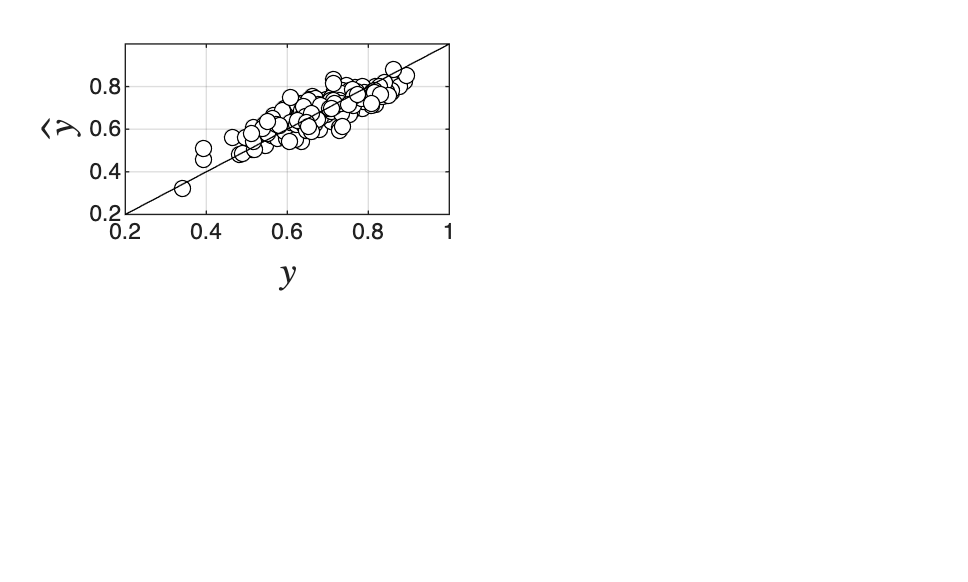


% compare predictions and observations
Yhat=dat.X*thetahat;
figure(1)
subplot(2,2,1)
xx=linspace(0,1);
plot(Y,Yhat,'blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0.2 1 0.2 1])

## compare with analytical solution

thetan=(X'*X)\(X'*Y)

thetan =    4.4351e-01
   1.7082e-02
   1.5226e+00
   3.8976e-01
   1.9729e+00
  -2.4356e-01


MSEn=msefun(thetan,dat)

MSEn =    2.4414e-03


% get hessian
H=X'*X

H =    2.5000e+02   2.4469e-13   6.9278e-14   1.3793e-12   5.2847e-14  -2.4950e+02
   2.4469e-13   2.4900e+02  -2.4294e+02  -2.4294e+02   2.4294e+02  -2.4292e-13
   6.9278e-14  -2.4294e+02   2.4900e+02   2.4900e+02  -2.4900e+02  -7.1054e-14
   1.3793e-12  -2.4294e+02   2.4900e+02   2.4900e+02  -2.4900e+02  -1.3807e-12
   5.2847e-14   2.4294e+02  -2.4900e+02  -2.4900e+02   2.4900e+02  -4.3077e-14
  -2.4950e+02  -2.4292e-13  -7.1054e-14  -1.3807e-12  -4.3077e-14   2.4900e+02


lam=eigs(H)

lam =    9.8694e+02
   4.9900e+02
   9.0564e+00
  -1.0491e-13
  -2.8897e-14
  -7.7843e-15


## solve regularized problem

kappa=logspace(-12,1,100);
for k=1:length(kappa)
dat.kappa=kappa(k);
options = optimoptions(@fmincon,'Algorithm','trust-region-reflective','display','none');
[theta] = fmincon(@myfun,theta,[],[],[],[],[],[],[],[],options,dat);

thetav(:,k)=theta;
MSE(k)=msefun(thetav(:,k),dat);
rho(k)=rhofun(thetav(:,k));

% count number of non-zero parameters
nnz(k)=sum(abs(thetav(:,k))>1e-4);

end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the

## compare fit to model with 3 parameters (keep input variables 1,3,4)

thetasparse=thetav(:,87)

thetasparse =    6.1404e-01
   6.9870e-12
  -2.1671e-06
  -2.8324e-06
   4.3410e-03
  -1.0564e-06


Xnew=[X(:,1),X(:,3),X(:,4)];
thetan=(Xnew'*Xnew)\(Xnew'*Y);
Yhat=Xnew*thetan;
datnew.X=Xnew;
datnew.y=Y;
MSEsparse=msefun(thetan,datnew)

MSEsparse =    NaN

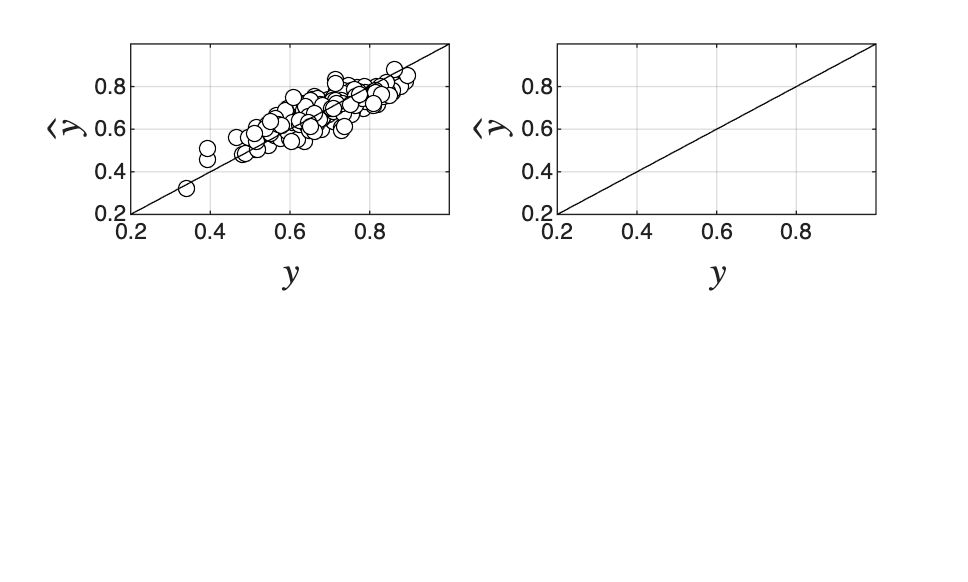


figure(1)
subplot(2,2,2)
xx=linspace(0,1);
plot(Y,Yhat,'blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)
axis([0.2 1 0.2 1])
print -depsc ch5_gibbs_fit.eps

## draw trade-off curve

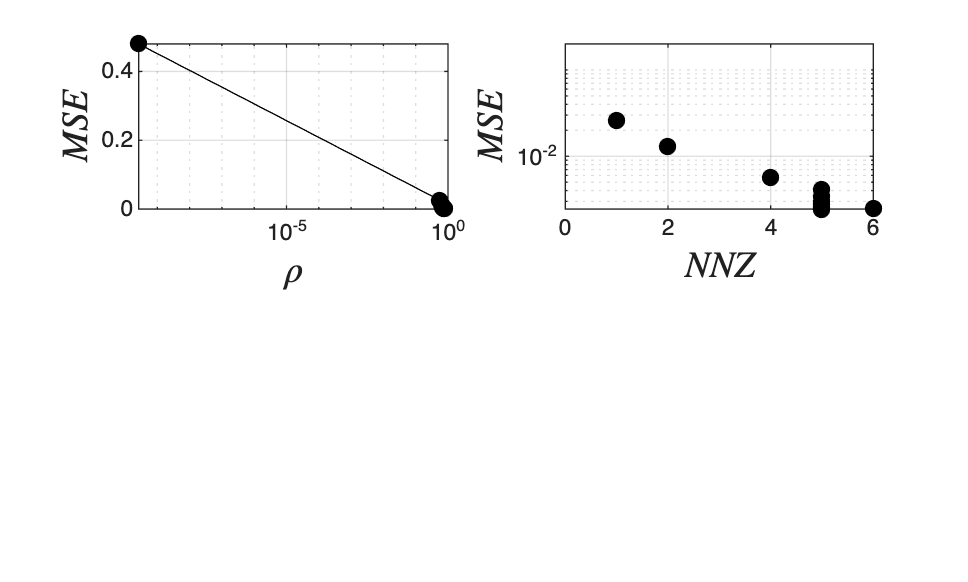

figure(2)
subplot(2,2,1)
semilogx(rho,MSE,'blacko-','MarkerFaceColor','black')
grid on
xlabel('$\rho$','Interpreter','latex','FontSize',14)
ylabel('$MSE$','Interpreter','latex','FontSize',14)
axis([min(rho) 1 0 max(MSE)])


subplot(2,2,2)
semilogy(nnz,MSE,'blacko','MarkerFaceColor','black')
grid on
xlabel('$NNZ$','Interpreter','latex','FontSize',14)
ylabel('$MSE$','Interpreter','latex','FontSize',14)
axis([0 6 0 0.2])

print -depsc ch5_gibbs_tradeoff.eps

## define SSE function

function MSE=msefun(theta,dat)

yhat=dat.X*theta;

MSE=mean((yhat-dat.y).^2);

end

## define penalty function

function rho=rhofun(theta)

rho=sum(abs(theta));

end

## define objective function

function F=myfun(theta,dummy,dat)

X=dat.X;
y=dat.y;
y=X*theta;

MSE=mean((y-dat.y).^2);
rho=sum(abs(theta));

F = MSE + dat.kappa*rho;

end

## Note

As in the book, X^T X has zero eigenvalues (the estimate is not unique), and a model with only three non-zero parameters fits about as well: regularization reduces model complexity.